# Compare Workspace of CAD and Parametric Robot

This example compares the workspace area of CAD geometry robot and its equivalent parametric robot.

Copyright 2023 The MathWorks, Inc.

To return to the main page within this repository, [click here](matlab:web('RobotDesignOverview.html')).

## Generate Workspace and Envelope for CAD Robot

Define the robot model and the rigid body representing end effector for the CAD model. 

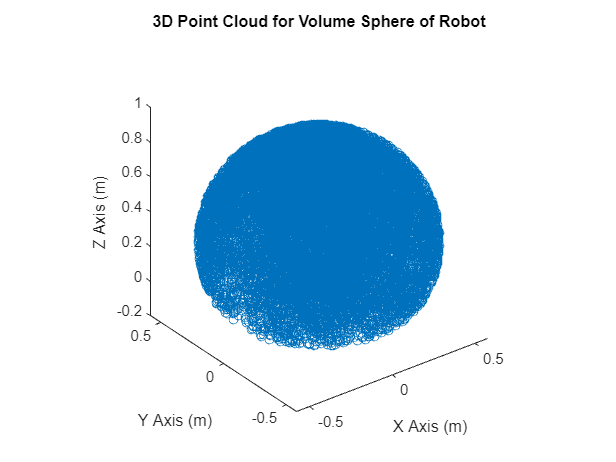

Generate the envelope of front-view


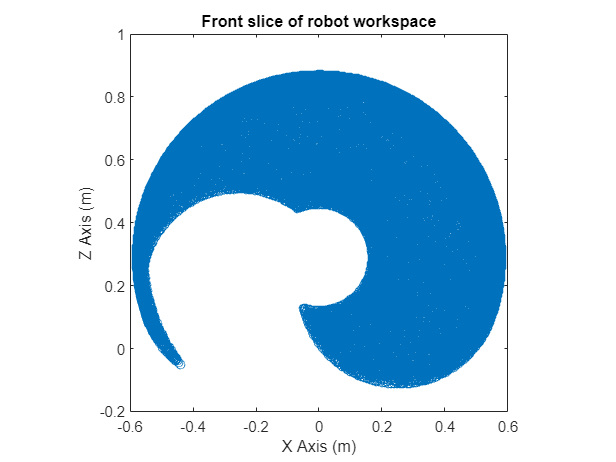

Generate the envelope of top-view


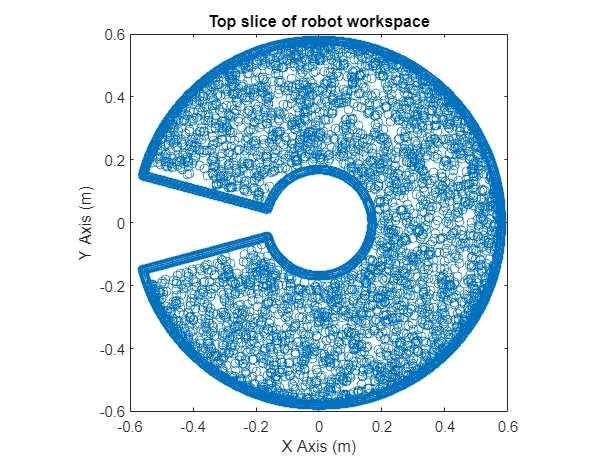

outerParams_CAD =     0.5799    0.3028


innerParams_CAD =     0.1663    0.3017


% Define the Robot model and end effector
modelRobot = 'sm_abbIrb120_1_RawImport';
endEffectorName = "Body5";

%% Import information from the model to rigid body tree structure. 
% This information includes all the design parameters and structural 
% details of the robot.
load_system(modelRobot);
robot = importrobot(modelRobot);
close_system(modelRobot);
robot.DataFormat = 'column';

% Run envelope generator script, read the comments in the scripts for
% better understanding
[outerParams_CAD, innerParams_CAD] = envelopeGenerator(robot, endEffectorName)

## Compare Workspace of Parametric Robot with CAD

Comparison of inner and outer radius of the workspace of CAD robot model and it's equivalent parametric model. The outer radius give the maximum reach of the robot and the inner radius is the minimum reach of the robot and are important parameters for workspace of the manipulator.

Plot inner and outer reach for CAD geometry robot.

figure
plotCircle(0,outerParams_CAD(2),outerParams_CAD(1));
hold on
plotCircle(0,innerParams_CAD(2),innerParams_CAD(1));
hold off
legend('CADOuterReach','CADInnerReach')

Plot inner and outer reach for parametric robot.

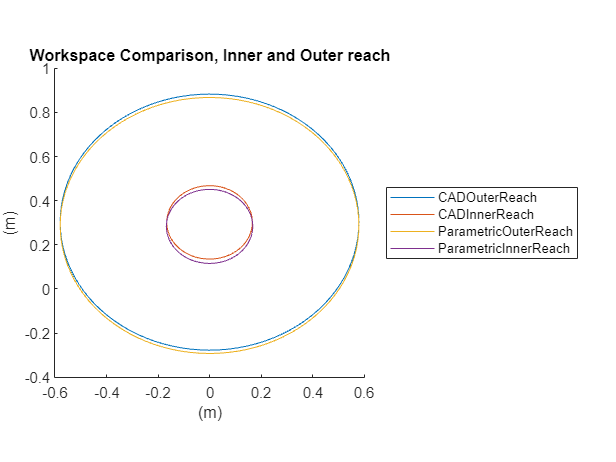

%figure
load('workspaceParametricRobotModel.mat');
plotCircle(0,outerParams_Parametric(2),outerParams_Parametric(1));
hold on
plotCircle(0,innerParams_Parametric(2),innerParams_Parametric(1));
hold off
fL = legend('CADOuterReach','CADInnerReach','ParametricOuterReach','ParametricInnerReach');
fL.Location = 'eastoutside';
title('Workspace Comparison, Inner and Outer reach');
xlabel('(m)');
ylabel('(m)');
axis square

## Useful Links

For details on workspace of  robot see [EnvelopeWorkflow](matlab:open('DetermineEnvelopeWorkflow.mlx'))

For a known work envelope and payload weight, you can size the electrical actuation components. To learn more about sizing electrical actuation components, see [ActuatorRatingWorkflow](matlab:open('ActuatorRatingWorkflow.mlx')).